Get the parameters:

[input, fname, fs2, type_signal, fs1, T, periodicity, frequencies,...
spectral_resolution, window, overlapSTFT, filterType, order, method, type, cutoffFrequencies , ...
xlimTime, ylimAmplitude, xAxisType, yAxisType,xlimFreq, ylimFreq] ...
=specs();

Reading line: "%% This is the specification file for the assingnment project in 22051."
Reading line: "% Use input signal or generated signal? Possible: wav, generate"
Reading line: "generate"
Reading line: "% WAV-filename"
Reading line: "mini-me_short.wav"
Reading line: "% Target sampling frequency (Hz) of the .wav file"
Reading line: "10000"
Reading line: "% SIGNAL GENERATOR"
Reading line: "% Type of signal. Possible: rect, tone, tone-complex, noise"
Reading line: "tone complex"
Reading line: "% Sampling frequency (Hz)"
Reading line: "20000"
Reading line: "% Overall duration of the signal (in s)"
Reading line: "4"
Reading line: "% Periodicity (s) - only applicable for "rect". The width of each rectangle should be half the period."
Reading line: "0.5"
Reading line: "% Frequency/-ies of the tone/tone complex (only first if 'tone'"
Reading line: "1000, 2000, 3000, 4000"
Reading line: "% FREQUENCY ANALYSIS"
Reading line: "% Spectral resolution (Hz)"
Reading line: "1"
Reading line: "% Win

Get the signal:

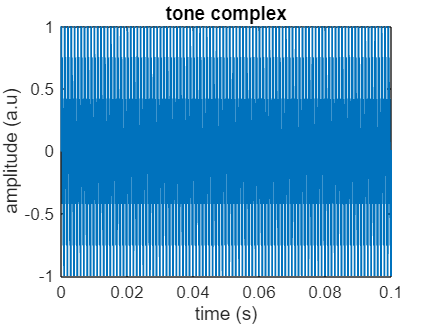

[y, fs, fn, t]= signals(input, type_signal, fs1, fs2, T, frequencies, fname, xlimTime, ylimAmplitude);

Do the frequency analysis: 

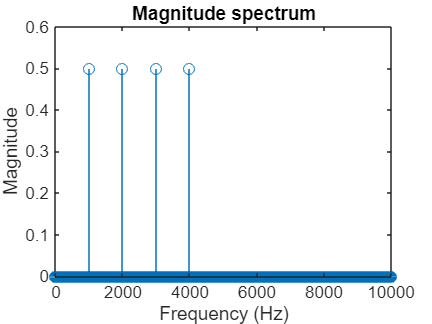

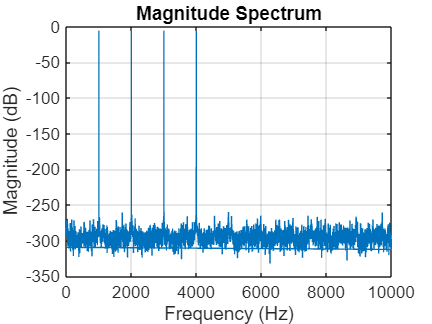

y =          0    2.6569    3.0777    1.4813    0.0000   -0.0000    0.7265    0.7548    0.0000   -0.4208   -0.0000    0.4208    0.0000   -0.7548   -0.7265   -0.0000    0.0000   -1.4813   -3.0777   -2.6569   -0.0000    2.6569    3.0777    1.4813    0.0000   -0.0000    0.7265    0.7548    0.0000   -0.4208   -0.0000    0.4208    0.0000   -0.7548   -0.7265   -0.0000    0.0000   -1.4813   -3.0777   -2.6569   -0.0000    2.6569    3.0777    1.4813    0.0000   -0.0000    0.7265    0.7548    0.0000   -0.4208


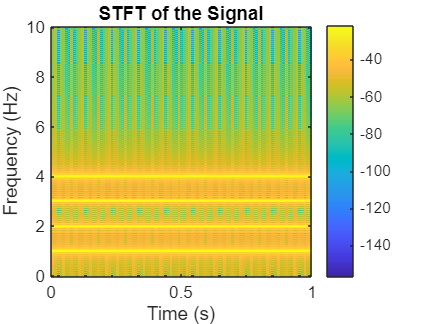

frequency(y, fs, spectral_resolution, window, xlimFreq, ylimFreq, overlapSTFT );

Filter the signal: 

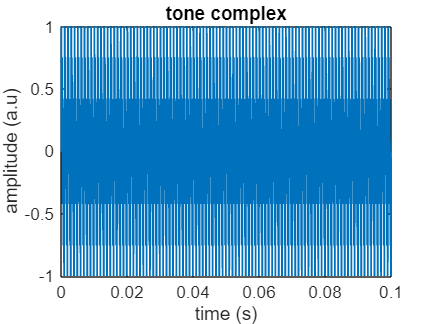

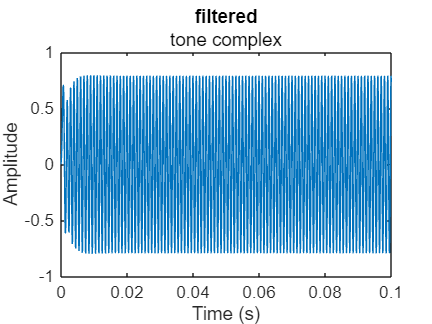

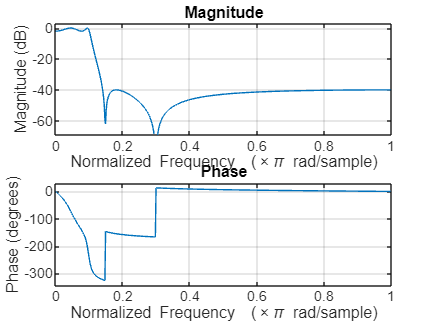

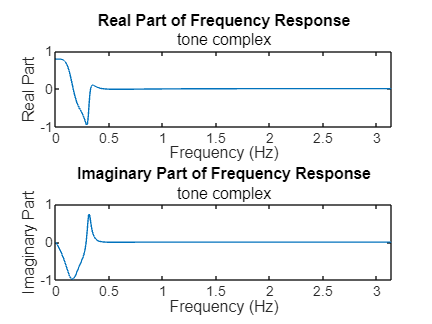

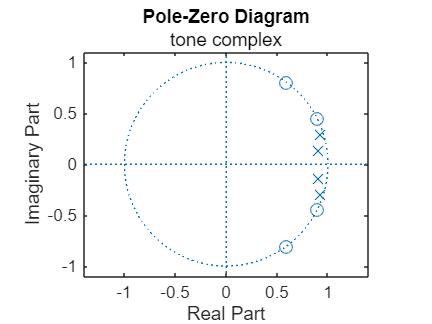

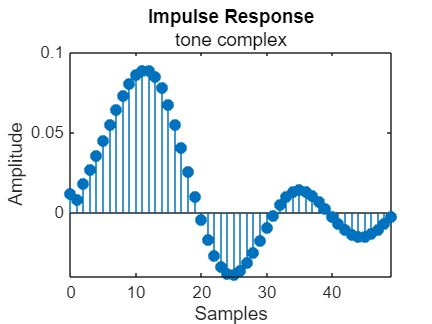

[t, filtered_signal]=filters(cutoffFrequencies, fn, filterType, method, type, order, y, fs, type_signal, input, fname, xlimTime, ylimAmplitude);

Frequency analysis of filtered signal: 

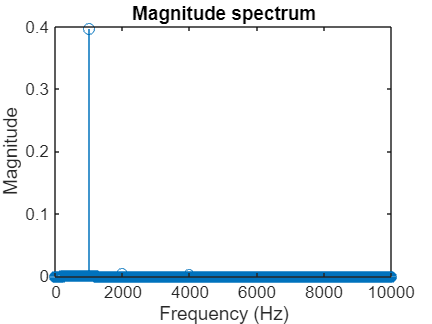

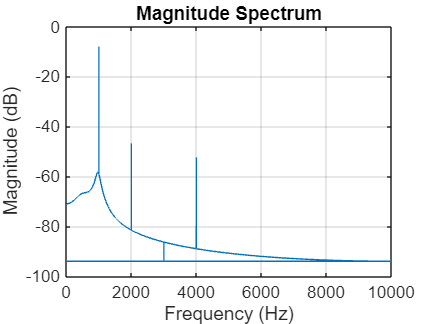

y =          0    0.0307    0.0571    0.0890    0.1372    0.2031    0.2776    0.3515    0.4243    0.4999    0.5757    0.6407    0.6847    0.7061    0.7071    0.6839    0.6260    0.5271    0.3936    0.2400    0.0771   -0.0905   -0.2562   -0.4047   -0.5187   -0.5895   -0.6197   -0.6127   -0.5656   -0.4733   -0.3400   -0.1809   -0.0128    0.1541    0.3124    0.4479    0.5402    0.5743    0.5496    0.4756    0.3609    0.2103    0.0332   -0.1506   -0.3174   -0.4515   -0.5479   -0.6035   -0.6089   -0.5549


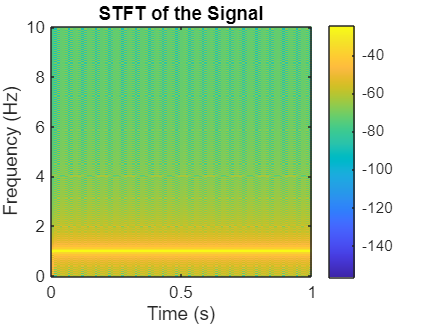

frequency(filtered_signal, fs, spectral_resolution, window, xlimFreq, ylimFreq, overlapSTFT );